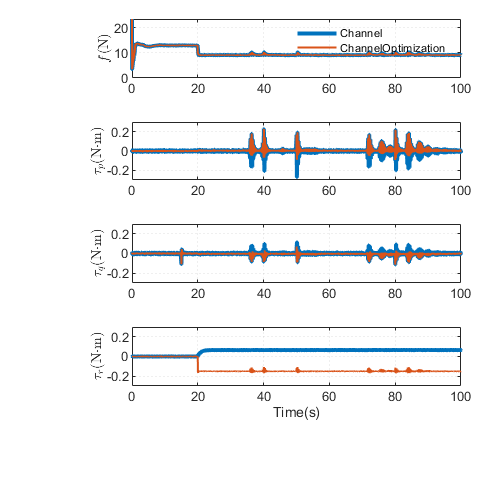

t = out.Channel.Time;
ControlChannel.f = out.Channel.Data(:,1);
ControlChannel.p = out.Channel.Data(:,2);
ControlChannel.q = out.Channel.Data(:,3);
ControlChannel.r = out.Channel.Data(:,4);

ControlChannel.fOptimization = out.ChannelOptimization.Data(:,1);
ControlChannel.pOptimization = out.ChannelOptimization.Data(:,2);
ControlChannel.qOptimization = out.ChannelOptimization.Data(:,3);
ControlChannel.rOptimization = out.ChannelOptimization.Data(:,4);

subplot(11,1,[1 2])
plot(t,ControlChannel.f,"Color",'#0072BD','LineWidth',3);
hold on
plot(t,ControlChannel.fOptimization,'Color','#D95319','LineWidth',1.5);
legend('Channel','ChannelOptimization','box','off',"Location","northeast")
ylabel('$f$(N)','Interpreter','latex')

subplot(11,1,[4 5])
plot(t,ControlChannel.p,"Color",'#0072BD','LineWidth',3);
hold on
plot(t,ControlChannel.pOptimization,'Color','#D95319','LineWidth',1.5);
ylim([-0.3 0.3])
ylabel('$\tau_{p}$(N$\cdot$m)','Interpreter','latex')

subplot(11,1,[7 8])
plot(t,ControlChannel.q,"Color",'#0072BD','LineWidth',3);
hold on
plot(t,ControlChannel.qOptimization,'Color','#D95319','LineWidth',1.5);
ylim([-0.3 0.3])
ylabel('$\tau_{q}$(N$\cdot$m)','Interpreter','latex')

subplot(11,1,[10 11])
plot(t,ControlChannel.r,"Color",'#0072BD','LineWidth',3);
hold on
plot(t,ControlChannel.rOptimization,'Color','#D95319','LineWidth',1.5);
ylim([-0.3 0.3])
ylabel('$\tau_{r}$(N$\cdot$m)','Interpreter','latex')
xlabel('Time(s)')